# [Image Classification: Bits and Cracks](https://apmonitor.com/pds/index.php/Main/BitClassification)

**Objective**: Train and test a Convolutional Neural Network to detect [**drilling bit types**](https://en.wikipedia.org/wiki/Drill_bit_well): [**roller cone**](https://petrowiki.spe.org/Roller_cone_bit_design), [**Polycrystalline Diamond Compact (PDC)**](https://petrowiki.spe.org/PDC_drill_bits), and spoon types.

Deep Learning (DL) is a subset of Machine Learning that uses Neural Network inspired architecture to make predictions. Convolutional Neural Networks (CNN) are a type of DL model that is effective in learning patterns in 2-dimensional data such as images. Images of drill bit types are used to train a classifier to identify common drill bit types for Oil & Gas Exploration and Horizontal Directional Drilling (HDD).

This exercise demonstrates the use of image classification to distinguish between objects in photos. Although applied to bit types, the same methods and code can be used for any type or number of objects. This example can be modified by including train and test photos in folders that are named with the object type. The code automatically takes the name of the folder as the photo label for training the classifier. An additional example of an image-based CNN is found in the [**Soil Classification Case Study**](https://apmonitor.com/pds/index.php/Main/SoilClassification).

**Getting Started**

This exercise uses photos of drill bit types in a compressed archive.

 [**Download: bit_photos.zip**](https://apmonitor.com/pds/uploads/Main/bit_photos.zip)

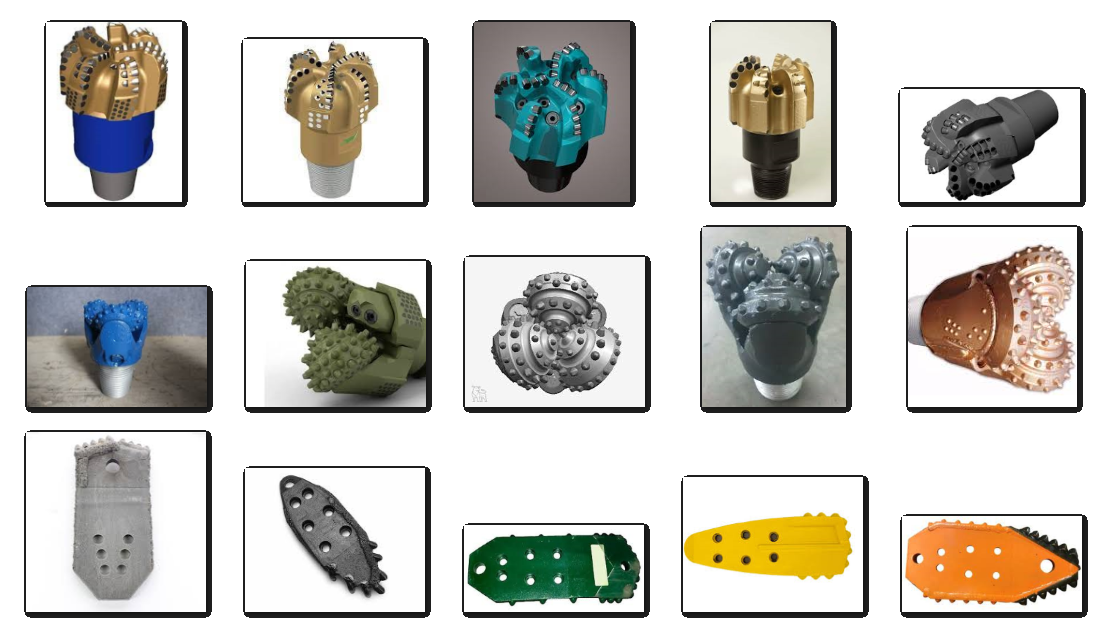

The archive contains two folders, a test folder and train folder with subdirectories corresponding to the possible drill bit types (PDC, Roller Cone, and Spoon). The images are found within each subdirectory. The tree structure of the folders is:

`  ├───test`

`  │   ├───PDC`

`  │   ├───Roller Cone`

`  │   └───Spoon`

`  └───train`

`   ├───PDC`

`      ├───Roller Cone`

`      └───Spoon`

The photos are imported into the Matlab session. The first step is to process the images into a format that 1) makes the data readable to the model, and 2) provides more training material for the model to learn. For example, the *train_processor* variable scales the data so that it can be a feature (input) for the model, but also takes each images and augments it so that the model can learn from multiple variations of the same picture. It flips it horizontally, rotates it, and shifts it, and more to make sure the model learns from the shape of the bit rather than the orientation or size.

Below is the code for bit classification

% Download the file
url = 'http://apmonitor.com/pds/uploads/Main/bit_photos.zip';
filename = 'bit_photos.zip';
outfilename = websave(filename,url);

% Unzip then deleate zip folder
unziped_folder = unzip(filename);
delete(filename);

augmenter = imageDataAugmenter( ...
    'RandRotation',[0 360], ...
    'RandScale',[0.5 1]);

% Data processing
train_processor = imageDataAugmenter( ...
    'RandScale', [.8 1.2], ...
    'RandXReflection', true, ...
    'RandRotation', [-45, 145], ...
    'RandXShear', [0 45], ...
    'RandYShear', [0 45], ...
    'RandXTranslation', [-5 5], ...
    'RandYTranslation', [-5 5], ...
    'RandYReflection', true);
test_processor = imageDataAugmenter('RandScale', [.8 1.2]);

train = imageDatastore('train\', 'IncludeSubfolders',true, ...
    'LabelSource','foldernames','ReadFcn',@imread);
train_preprocess = augmentedImageDatastore([255,255],train);

**Neural Network**

Change these values to modify the training neural network. Beware, the larger the values, the longer and more computer memory demand will be required. This is a starting point and should take roughly 10 minutes.

num_conv_layers = 3;
num_dense_layers = 2;
layer_size = 64;
num_training_epochs = 20;

Build the Neural Network based on the values above

layers = [
    imageInputLayer([255 255 3])
    convolution2dLayer([3 3],layer_size,"Padding","same")
    reluLayer()
    maxPooling2dLayer([2 2],"Padding","same")];

% Add additional convolutional layers based on num_conv_layers
for i = 1:num_conv_layers-1
    layers = [layers
              convolution2dLayer([3 3],layer_size,"Padding","same")
              reluLayer()
              maxPooling2dLayer([2 2],"Padding","same")];
end
layers = [layers
          flattenLayer()];
for i = 1:num_dense_layers
    layers = [layers
              fullyConnectedLayer(layer_size)
              reluLayer()];
end
layers = [layers
          fullyConnectedLayer(3)
          softmaxLayer()
          classificationLayer()];

options = trainingOptions("adam", ...
    InitialLearnRate=0.01, ...
    SquaredGradientDecayFactor=0.99, ...
    MaxEpochs=num_training_epochs, ...
    MiniBatchSize=32, ...
    Verbose=true,...
    Plots="training-progress");

Train Neural Network (estimated time: 10 minutes)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:57 |       50.00% |       3.0060 |          0.0100 |
|      20 |          20 |       00:20:44 |      100.00% |   0.0000e+00 |          0.0100 |
|========================================================================================|
Training finished: Max epochs completed.


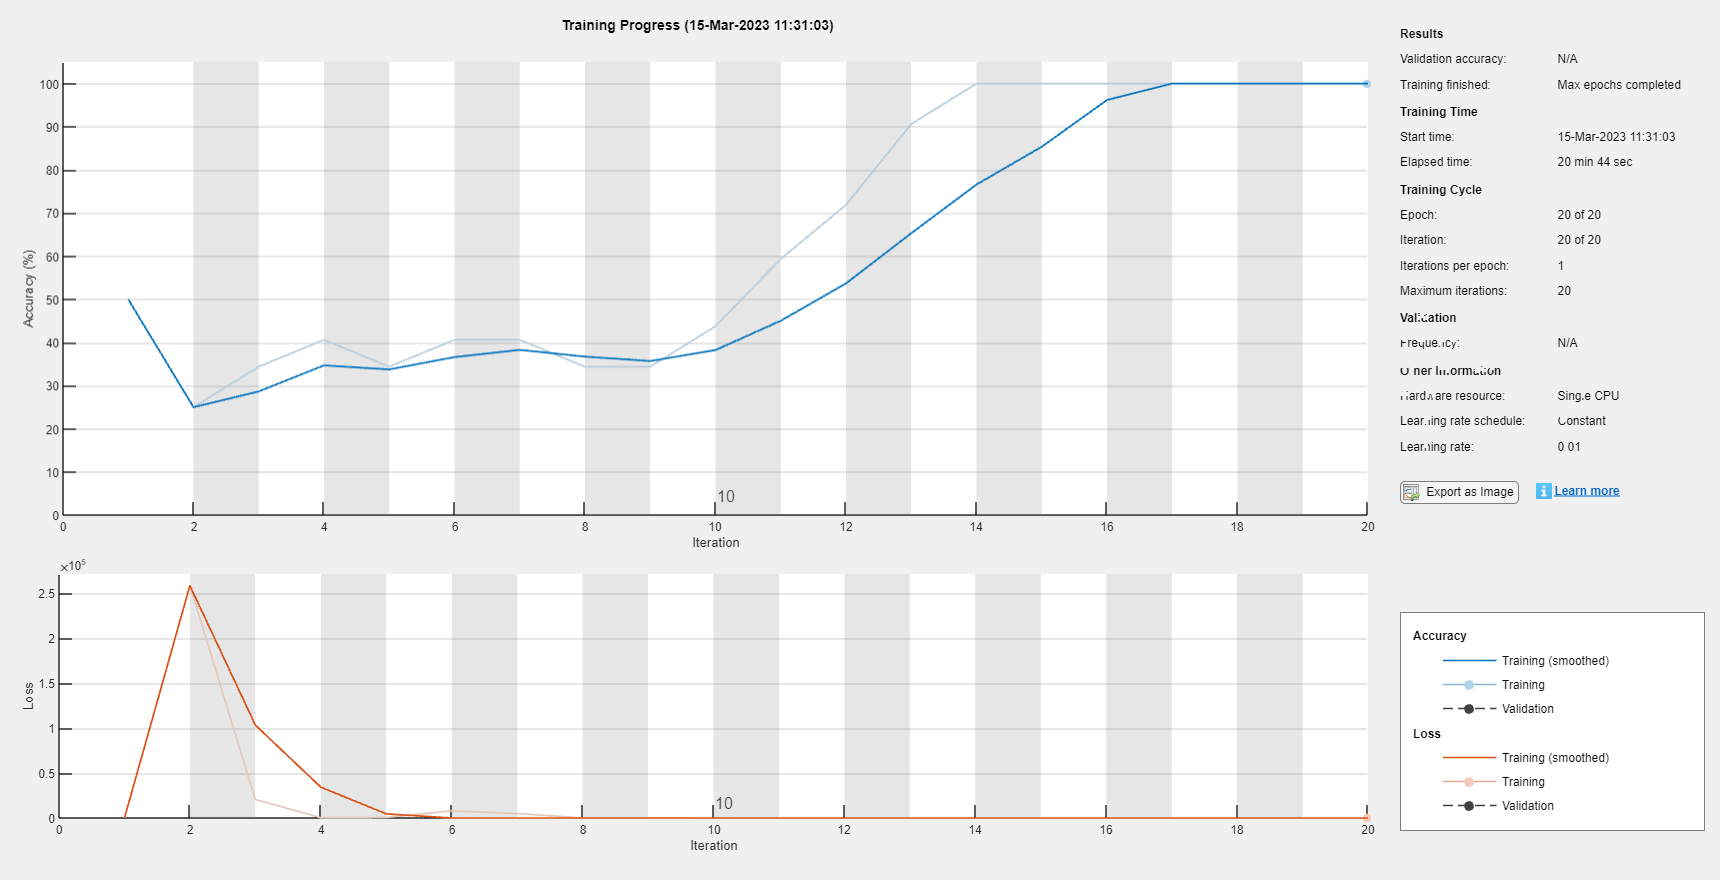

[net,info] = trainNetwork(train_preprocess, layers, options);

Grab random test drill bit and predict the type.

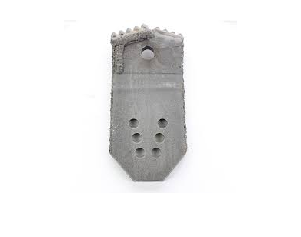

% Grab random picutre
btype = ["PDC", "Roller Cone", "Spoon"]; % possible output values
bbtype = ["PDC", "Roller_Cone", "Spoon"]; % possible output values
rng('shuffle');
i=randi(3);
j=randi(5);
b = btype(i);
bb = bbtype(i);
im = strcat(lower(strrep(strcat(bb,'_',num2str(j),'.jpg'),'',"")));
test_image_filepath = fullfile('./test',b,im);

% Show image
image_fp = test_image_filepath;
ime = imread(image_fp); % load image
imshow(ime);


% Modify image to fit Neural Network
im = double(imresize(ime,[255 255]));
image_array = im / 255.0; % scale the image
img_batch = reshape(image_array, [size(image_array)]);

% Prediction
predicted_value = net.classify(im)

predicted_value = categorical
     Roller Cone 


true_value = regexp(image_fp, "(PDC)|(Roller Cone)|(Spoon)", 'match');
true_value = true_value{1}

true_value = 'Spoon'

## Exercise

Replace the photos in the bit classification case study to build a classifier to distinguish photos of concrete with a crack (Positive) or no crack (Negative).

 [**Download: concrete_cracks.zip**](https://apmonitor.com/pds/uploads/Main/concrete_cracks.zip)

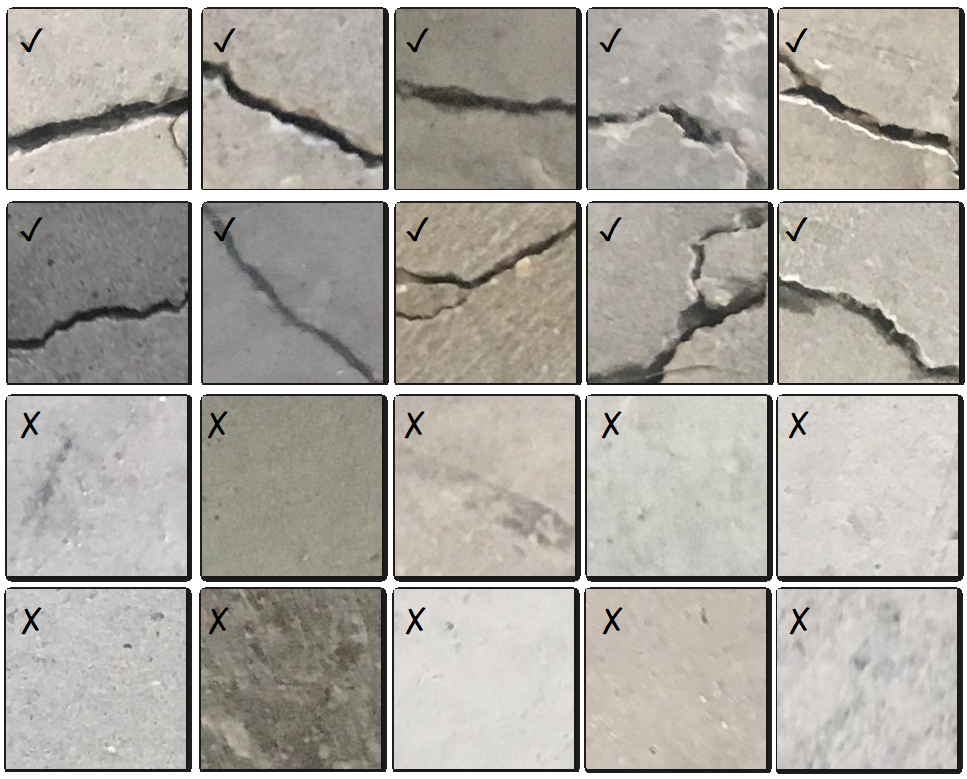

The images are found within each subdirectory. The tree structure of the folders is:

`  ├───test`

`  │   ├───Positive`

`  │   └───Negative`

`  └───train`

`      ├───Positive`

`      └───Negative`

The dataset is divided into two (negative and positive) crack image folders for image classification. Each train folder has 500 images with a total of 1000 images with 227 x 227 pixels with RGB channels. The test folders have 100 images from the full image set for a total of 200 test images. The partial dataset trains much faster and gives similar accuracy (95%) versus 97% for the full data set with 40,000 images.

 Clean the workspace and the folders from above.

clear;
[~, ~, ~] = rmdir('train','s');
[~, ~, ~] = rmdir('test','s');

url = 'http://apmonitor.com/pds/uploads/Main/concrete_cracks.zip';
filename = 'concrete_cracks.zip';
outfilename = websave(filename,url);

% Unzip then deleate zip folder
unziped_folder = unzip(filename);
delete(filename);

augmenter = imageDataAugmenter( ...
    'RandRotation',[0 360], ...
    'RandScale',[0.5 1]);

% Data processing
train_processor = imageDataAugmenter( ...
    'RandScale', [.8 1.2], ...
    'RandXReflection', true, ...
    'RandRotation', [-45, 145], ...
    'RandXShear', [0 45], ...
    'RandYShear', [0 45], ...
    'RandXTranslation', [-5 5], ...
    'RandYTranslation', [-5 5], ...
    'RandYReflection', true);
test_processor = imageDataAugmenter('RandScale', [.8 1.2]);


% Load data
% train = augmentedImageDatastore([255,255], unziped_folder, 'train_2', train_processor)

train = imageDatastore('train\', 'IncludeSubfolders',true, ...
    'LabelSource','foldernames','ReadFcn',@imread);
train_preprocess_con = augmentedImageDatastore([128,128],train);

**Neural Network**

Change these values to modify the training neural network. Beware, the larger the values, the longer and more computer memory demand will be required. This is a starting point and should take roughly 10 minutes.

num_conv_layers = 4;
num_dense_layers = 3;
layer_size = 16;
num_training_epochs = 5;

Build the Neural Network based on the values above

layers = [
    imageInputLayer([128 128 3])
    convolution2dLayer([3 3],layer_size,"Padding","same")
    reluLayer()
    maxPooling2dLayer([2 2],"Padding","same")];

% Add additional convolutional layers based on num_conv_layers
for i = 1:num_conv_layers-1
    layers = [layers
              convolution2dLayer([3 3],layer_size,"Padding","same")
              reluLayer()
              maxPooling2dLayer([2 2],"Padding","same")];
end
layers = [layers
          flattenLayer()];
for i = 1:num_dense_layers
    layers = [layers
              fullyConnectedLayer(layer_size)
              reluLayer()];
end
layers = [layers
          fullyConnectedLayer(2)
          softmaxLayer()
          classificationLayer()];

options = trainingOptions("adam", ...
    InitialLearnRate=0.01, ...
    SquaredGradientDecayFactor=0.99, ...
    MaxEpochs=num_training_epochs, ...
    MiniBatchSize=32, ...
    Verbose=true,...
    Plots="training-progress");

Train Neural Network (estimated time: 5 minutes)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |       53.12% |       3.8046 |          0.0100 |
|       2 |          50 |       00:01:03 |       75.00% |       0.4988 |          0.0100 |
|       4 |         100 |       00:02:14 |      100.00% |       0.1922 |          0.0100 |
|       5 |         150 |       00:04:12 |      100.00% |       0.0458 |          0.0100 |
|       5 |         155 |       00:04:24 |      100.00% |       0.0395 |          0.0100 |
|========================================================================================|
Training finished: Max epoc

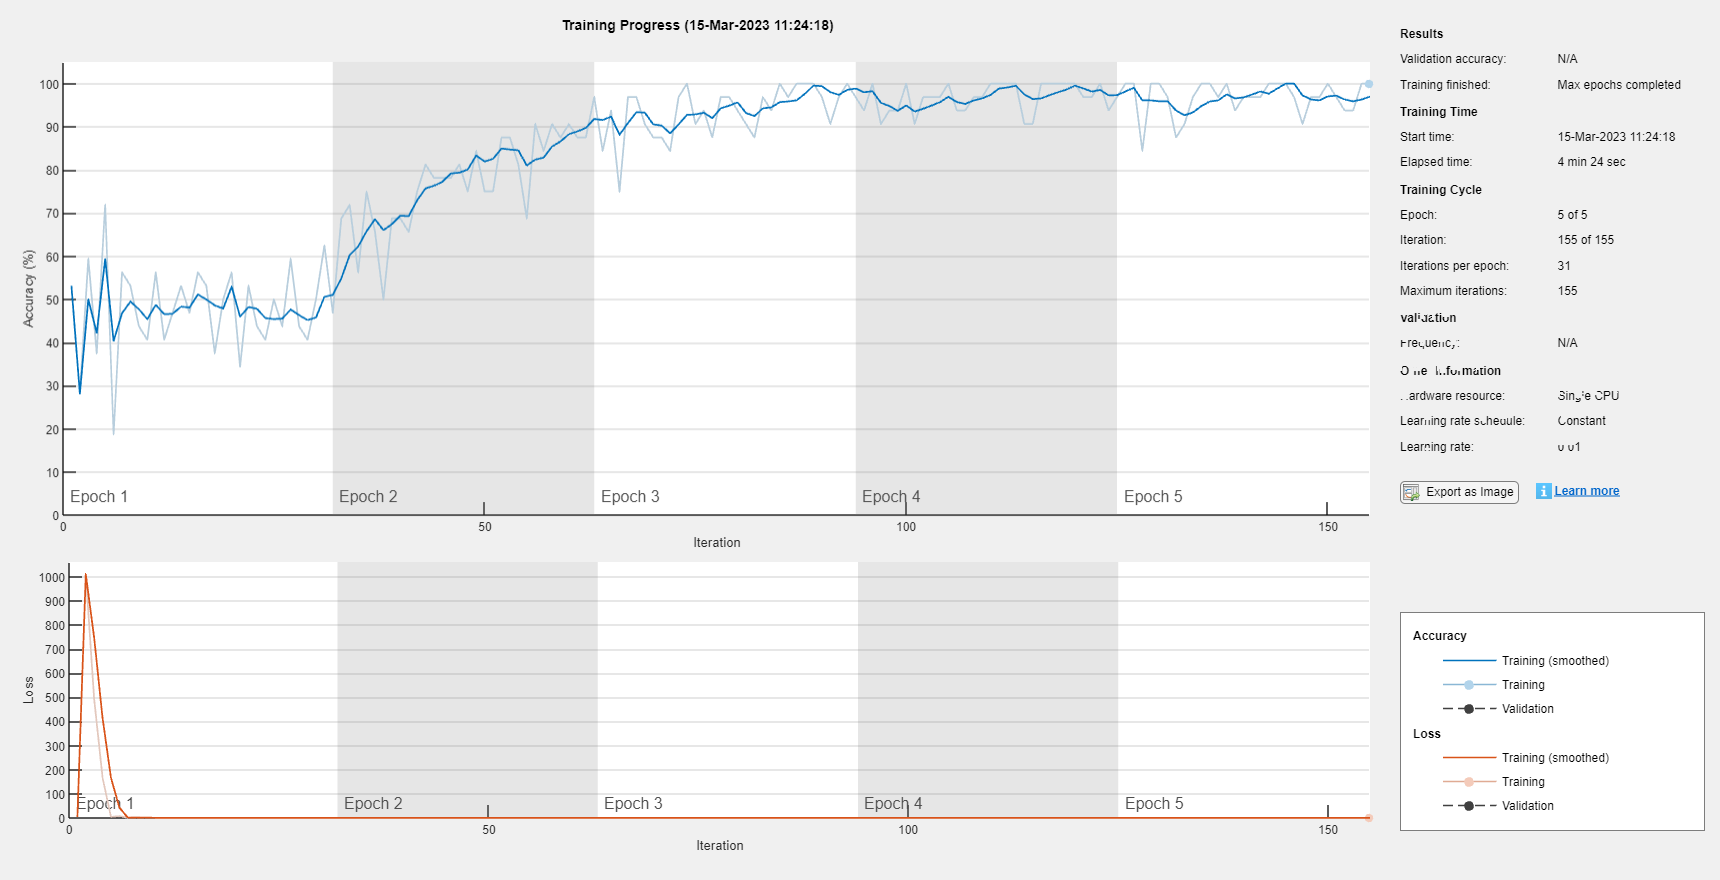

[net,info] = trainNetwork(train_preprocess_con, layers, options);

Grab random test image and predict the type.

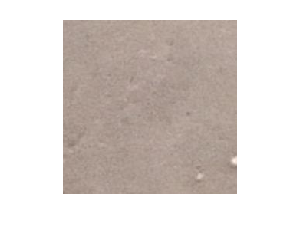

btype = ["Positive", "Negative"]; % possible output values
rng('shuffle');
i=randi(2);
j=randi([19901,20000]);
b = btype(i);
im = strcat(lower(strrep(strcat(num2str(j),'.jpg'),'',"")));
test_image_filepath = fullfile('./test',b,im);

image_fp = test_image_filepath;
ime = imread(image_fp); % load image
imshow(ime);


im = double(imresize(ime,[128 128]));
image_array = im / 255.0; % scale the image
img_batch = reshape(image_array, [size(image_array)]);

predicted_value = net.classify(im)

predicted_value = categorical
     Negative 


true_value = regexp(image_fp, "(Positive)|(Negative)", 'match');
true_value = true_value{1}

true_value = 'Negative'